## Spike detection and spike rate analysis week 2, tutorial 1

In this live script we will show some of the basics of reading ephys data into matlab, detect spikes in the recording and averaging the signal of multiple spikes

Tutorial using data from [https://github.com/wagenadl/mbl-nsb-toolbox](https://github.com/wagenadl/mbl-nsb-toolbox)

clc
close all
clear

# Part 1 - Read and visualize extracellular recordings 

1. load the electrical recordings

load('spike_train_data_w2t1.mat')


2. load the time stamps of each data point

 % $$$

**Inspect the data**

A. What is the data size?

datasize = 

 % $$$

B. What is the first and the last time point?

firsttime = 

lasttime =

% define firsttime and lasttime from tms
% $$$
% $$$

C. What is the sampling of the signal? 

Use the formula below to identify the sampling rate

srate = n samples/recording time

% $$$

3. plot data from channel 8

figure;
% $$$

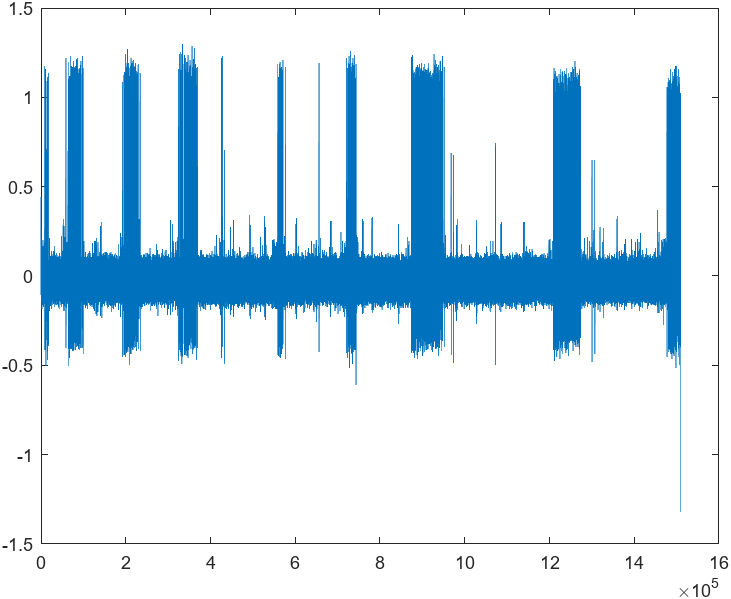

4. Plot the same data aligned with the correct time stamps (add labels to axis)

% add label 'Time (s)' to x axis and 'Voltage (V)' to y axis
figure;
% $$$

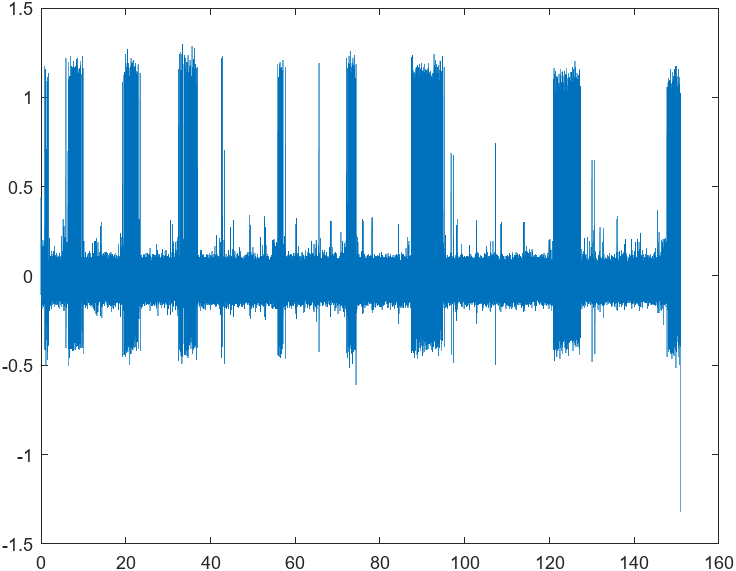

5. Plot only the first 10 secs of data for channel 8 (use srate)

figure;
% $$$

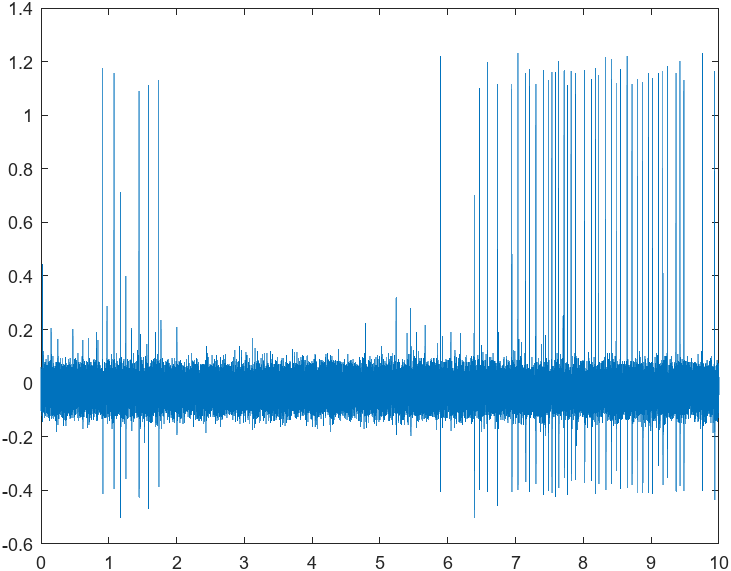

# Part 2 - Detect spikes based on absolute threshold 

6a. Select a single channel, 8, and create a vector with only the data of that channel

chan = 

cdata = data of chan

% $$$

6b. Select a reasonable threshold based on the figures you've plotted

threshold = 

% threshold for peak detection
% $$$

7. Get the data point where cdata values > threshold

*TIP: go to warm_up.mlx on how to use relational operators*

idx_above     = 

% get indices of values above threshold
% $$$

A. What kind of variable is "idx_above"?

.

B. How do you find the indices of the data points above threshold from "idx_above"

spike_indices =

% $$$

8. Get the time (in seconds) where each spike occured

*TIP: use spike_indices to get the values in tms corresponding to the times needed*

spike_times = 

% Extract spike times (in seconds)
% $$$

Plot the data + a circle at a time of choice

time_p = 

figure; 
plot(tms, cdata); hold on

% % set a time point of choice
% time_p = ; % $$$
% plot(time_p, 0, 'go', 'LineWidth', 10); hold on

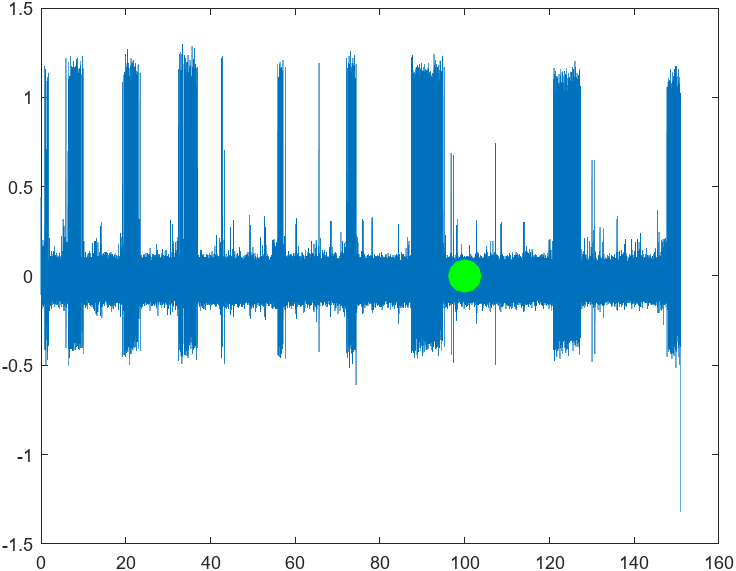

9. Plot the data + spike peaks and times

Use the optional argument 'rx' to make the peaks more visible

figure;
plot(tms, cdata); hold on 
% $$$

A. Does the plot look representative of the spike peaks?

B. What could be made to improve it?

# Part 3 - Automatically detect peaks 

Let's use a more generalizable threshold in the form of a z-value corresponding to z x SD of the data

10. Set a z-value threshold

zthreshold = 

% $$$

set minimum peak height and minimum peak distance

% Minimum peak height
min_peak_height = zthreshold * std(cdata);
% Minimum distance between peaks in samples
min_peak_distance = 0.001 * srate;

11. Use MATLAB findpeaks function to detect spikes distanced from each other by min peak distance

[peak_values, peak_indices] = findpeaks(cdata, 'MinPeakHeight', min_peak_height, 'MinPeakDistance', min_peak_distance);

%% Extract spike times (in seconds)
%spike_times =  % $$$

12. Plot the data + spike peaks and times

*use *plot* with the optinal arguments 'g.' and 'MarkerSize', 10, for better visualization

figure; 
plot(tms, cdata); hold on
% $$$

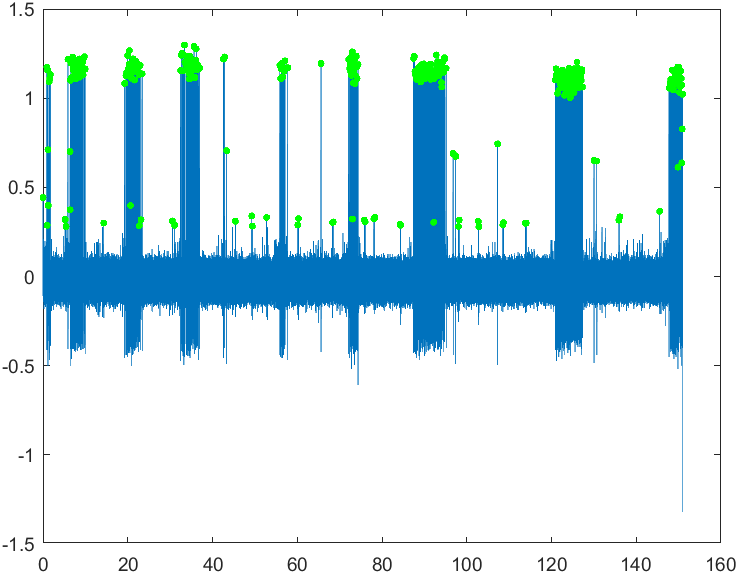

A. Is the threshold good enough?

B. What would you do to be more selective?

13. Set another threshold

zthresholdH = 

 % $$$

set minimum peak height and minimum peak distance

% Minimum peak height
min_peak_height = zthresholdH * std(cdata);
% Minimum distance between peaks in samples
min_peak_distance = 0.01 * srate;

14. Use MATLAB findpeaks function to detect spikes distanced from each other by min peak distance

[peak_valuesH, peak_indicesH] = findpeaks(cdata, 'MinPeakHeight', min_peak_height, 'MinPeakDistance', min_peak_distance);

% use new spike time estimates
spike_indices = peak_indicesH;
spike_times = tms(spike_indices);


15. Plot the data + spike peaks from both thresholds on the same figure

*use *plot* with the optinal arguments 'g.' , 'r.' and 'MarkerSize', 10, for better visualization

figure;
plot(tms, cdata); hold on
% $$$
% $$$

# Part 4 - Calculate firing rate 

16a. Calculate the number of spikes along the whole recording

 % $$$

16b. Estimate the firing rate along the whole recording (pretend the whole recording is representative of a single condition

frate = n spikes/time (in secs gives response in Hz)

% $$$

17. Compute the firing rate over time

% Bin size in seconds
bin_size = 0.1; 
% set the limits of each bin_size length window
edges = 0:bin_size:max(tms);
% get the counts
hist_counts = histcounts(spike_times, edges);
firing_rate = hist_counts / bin_size;

# Part 5 - Calculate interspike intervals (ISIs)

Use the function diff to quickly obtain the difference between spike times

% Calculate time differences between successive spikes
% ISI in seconds 
% $$$

# Part 6 - Plot the results

% 1. Plot the raw signal and detected spikes
figure;
subplot(3, 1, 1);
% $$$
plot(spike_times, cdata(peak_indicesH), 'r.', 'MarkerSize', 10) % $$$
title('Raw Signal with Detected Spikes');
xlabel('Time (s)'); ylabel('Amplitude (V)');

% Plot the firing rate
subplot(3, 1, 2);
plot(edges(1:end-1) + bin_size/2, firing_rate);
title('Firing Rate');
xlabel('Time (s)'); ylabel('Firing Rate (Hz)');

% Plot ISI distribution
subplot(3, 1, 3);
histogram(isi, 500);
xlim([-0.1 1])
ylim([0 200])
title('Interspike Interval Distribution');
xlabel('ISI (s)'); ylabel('Count');

# Part 7 - Average spikes

18. Get segments of the time series corresponding to spikes

*TIP: go to warm_up.mlx on the "using for loop" section*

% set up a windows size in secs
win_ap = 0.01*srate;

for segment = 1:length(spike_indices)
    i = spike_indices(segment);
    stepo = i - win_ap;
    endepo = i + win_ap;
    aps(segment,:) = cdata(stepo:endepo);
end

19. Change the for loop above in a way that every AP is automatically plotted on a figure

20. Get the average spike from "aps"

TIP: use the function mean in the same way std (i.e. standard deviation) was used before

21. Plot the average spike